## **Gamma**

For each distribution, anwser the following questions:

- Is the RV discrete or continuous? **Continuous**

- What is the domain of the RV's PDF or PMF ? **Positive real numbers**

- Describe the parameters of the distribution: how many are they? What values can they take?  **Shape and scale, a and b**

- Give one example of real world phenomenon or data that could be modelled using the distribution. **Diameter of a tennis ball**

and complete the following tasks:

- Plot the (theoretical) PDF (for contiuous RVs) or PMF (for discrete RVs) and the mean

- Draw a sample of $S=1000$ random outcomes.

- Plot the empirical PDF or PMF of these samples on the same plot created in task 1.

- Plot the (theoretical) CDF

- Plot the empirical CDF of the samples generated in task 2 on the same plot created in task 4.

- Use a Q-Q plot to show the similarity between empirical and theoretical quantiles.

pd = makedist('Gamma', 'a', 6540, 'b', 0.001)

pd =   GammaDistribution

  Gamma distribution
    a =  6540
    b = 0.001


outcomes = 6:0.01:7;
th_pdf = pdf(pd, outcomes)

th_pdf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0009    0.0016    0.0026    0.0043    0.0068    0.0108    0.0167    0.0254    0.0381    0.0561    0.0813    0.1159    0.1625    0.2243    0.3045    0.4067    0.5346    0.6914    0.8800    1.1023    1.3588    1.6486    1.9686    2.3140    2.6773    3.0494    3.4192    3.7744    4.1022


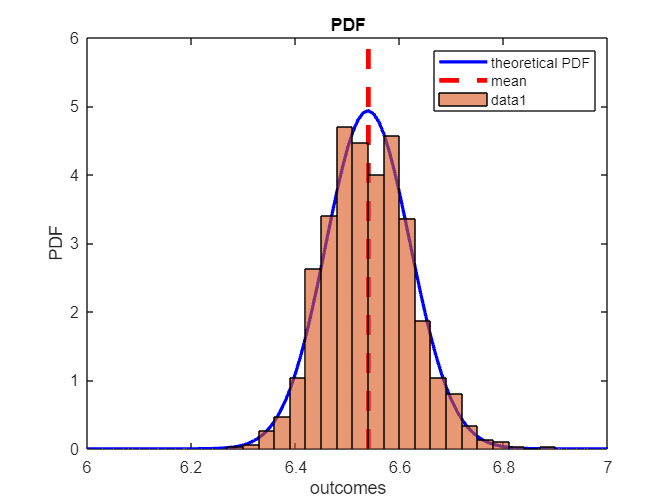

% Create small and large samples
sample = random(pd,1,1000);

% Generate plot data
clf; % clear the figure
plot(outcomes, th_pdf, 'b', 'LineWidth', 2)
hold on
th_mean = mean(pd); % Let's plot the distribution mean
line([th_mean,th_mean],[0,6], 'LineStyle', '--', 'Linewidth', 3,'Color','red');
legend('theoretical PDF', 'mean', 'Location','northeast')
title('PDF') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

th_epmf = histogram(sample, 'normalization', 'pdf'); % correctly normalised

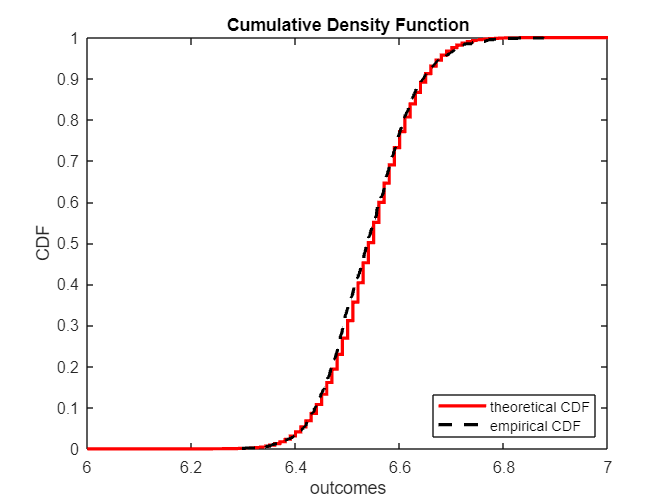

% Create cumulative density function
th_cdf = cdf(pd, outcomes);

clf % clear the plot
stairs(outcomes, th_cdf, '-r', 'LineWidth', 2)
hold on
legend('theoretical CDF', 'Location','southeast')
title('Cumulative Density Function') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label

[x_ecdf, y_ecdf] = ecdf(sample);
stairs(y_ecdf, x_ecdf, '--k', 'LineWidth',2)
legend('theoretical CDF','empirical CDF')

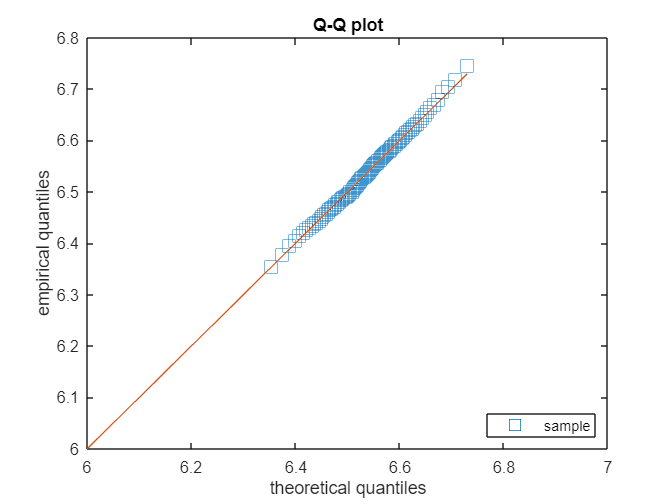

% evaluate at more points within 0 and 1
clf
pp = 0: 0.01: 1;
theor_q = icdf(pd, pp);
empir_q = quantile(sample, pp);
plot(theor_q, empir_q, 's', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
xlim([6,7])
legend('sample', 'Location','southeast')
title('Q-Q plot') % title for plot
xlabel('theoretical quantiles') % x-axis label
ylabel('empirical quantiles') % y-axis label